% where is your nwb file located?
path_to_nwb = "D:\scratch\mouse_preJan30\sub-1197684876_ses-1213341633.nwb";

% load nwb
nwb = nwbRead(path_to_nwb)

nwb =   NwbFile with properties:

                                             nwb_version: '2.4.0'
                                        file_create_date: [1×1 types.untyped.DataStub]
                         general_source_script_file_name: []
                                              identifier: 'sub-1197684876_ses-1213341633'
                                     session_description: 'Data and metadata for an Ecephys session'
                                      session_start_time: 2022-09-22T00:00:00.000000-07:00
                               timestamps_reference_time: 2022-09-22T00:00:00.000000-07:00
                                             acquisition: [10×1 types.untyped.Set]
                                                analysis: [0×1 types.untyped.Set]
                                                 general: [0×1 types.untyped.Set]
                                 general_data_collection: []
       

% notice that many fields are empty. This is because nwb defines certain
% categories that can be populated - it is our duty to populate the correct
% fields with their relevant information. that means for data types which
% we don't deal with (e.g., optophysiology), our files will always have
% that field empty.

% print the session id, institution, and lab!
disp([nwb.identifier '   ' nwb.general_lab '   ' nwb.general_institution])

sub-1197684876_ses-1213341633      Allen Institute


% ElectricalSeries is an nwb class that usually houses data such as LFP,
% MUA, etc... does this file have any electrical series data present? This
% searchFor function built into the nwb toolkit is something that could
% come in handy with files you are unfamiliar with
nwb.searchFor('electricalseries')

ans =   Map with properties:

        Count: 8
      KeyType: char
    ValueType: any


% useful data will be stored in a few places, e.g.:
nwb.general_extracellular_ephys

ans =   6×1 Set array with properties:

    probeA: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]
    probeB: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]
    probeC: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]
    probeD: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]
    probeE: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]
    probeF: [types.ndx_aibs_ecephys.EcephysElectrodeGroup]


nwb.general_extracellular_ephys_electrodes

ans =   DynamicTable with properties:

       colnames: {13×1 cell}
    description: 'metadata about extracellular electrodes'
             id: [1×1 types.hdmf_common.ElementIdentifiers]
     vectordata: [13×1 types.untyped.Set]


nwb.acquisition

ans =   10×1 Set array with properties:

                     EyeTracking: [types.ndx_ellipse_eye_tracking.EllipseEyeTracking]
                     probe_0_lfp: [types.core.LFP]
                     probe_1_lfp: [types.core.LFP]
                     probe_2_lfp: [types.core.LFP]
                     probe_3_lfp: [types.core.LFP]
                     probe_4_lfp: [types.core.LFP]
                     probe_5_lfp: [types.core.LFP]
      raw_running_wheel_rotation: [types.core.TimeSeries]
    running_wheel_signal_voltage: [types.core.TimeSeries]
    running_wheel_supply_voltage: [types.core.TimeSeries]


nwb.units

ans =   Units with properties:

          electrode_group: []
               electrodes: []
         electrodes_index: []
            obs_intervals: []
      obs_intervals_index: []
              spike_times: [1×1 types.hdmf_common.VectorData]
        spike_times_index: [1×1 types.hdmf_common.VectorIndex]
            waveform_mean: [1×1 types.hdmf_common.VectorData]
              waveform_sd: []
                waveforms: []
          waveforms_index: []
    waveforms_index_index: []
                 colnames: {29×1 cell}
              description: [1×0 char]
                       id: [1×1 types.hdmf_common.ElementIdentifiers]
               vectordata: [29×1 types.untyped.Set]


nwb.processing

ans =   5×1 Set array with properties:

    convolved_spike_train: [types.core.ProcessingModule]
              optotagging: [types.core.ProcessingModule]
                  running: [types.core.ProcessingModule]
              spike_train: [types.core.ProcessingModule]
                 stimulus: [types.core.ProcessingModule]


nwb.intervals

ans =   7×1 Set array with properties:

    create_receptive_field_mapping_presentations: [types.core.TimeIntervals]
                      init_grating_presentations: [types.core.TimeIntervals]
                 init_intermission_presentations: [types.core.TimeIntervals]
                                     optotagging: [types.core.TimeIntervals]
                                     passive_glo: [types.core.TimeIntervals]
                                      rf_mapping: [types.core.TimeIntervals]
                       spontaneous_presentations: [types.core.TimeIntervals]


% because nwb files keep data in storage until requested, you will have to
% 'get' the data you want...take for example:
nwb.acquisition.get('probe_0_lfp')

ans =   LFP with properties:

    electricalseries: [1×1 types.untyped.Set]


% however, we still aren't at the data! because I formatted this to match
% AIBS nwb specs, you will find that data tend to be buried under several
% layers of hierarchical input. Let's dig deeper...
nwb.acquisition.get('probe_0_lfp').electricalseries

ans =   Set with properties:

    probe_0_lfp_data: [types.core.ElectricalSeries]


% looks like we still aren't there quite yet...and it looks like this will
% be a call to a named variable rather than a class, so we have to 'get'
% the data.
% What do I mean by this. nwb recognizes classes, but when you arrive at a
% data type that was named specifically by the user (e.g., Jake named the
% lfp data 'probe_0_lfp_data'), that information has to be retrieved by the
% get function.
% let's keep digging...
nwb.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data')

ans =   ElectricalSeries with properties:

    channel_conversion_axis: 1
                 electrodes: [1×1 types.hdmf_common.DynamicTableRegion]
         channel_conversion: []
                  filtering: '4th order Butterworth 1-250 Hz'
         starting_time_unit: 'seconds'
        timestamps_interval: 1
            timestamps_unit: 'seconds'
                       data: [1×1 types.untyped.DataStub]
                  data_unit: 'uV'
         starting_time_rate: 1000
                   comments: 'no comments'
                    control: []
        control_description: []
            data_continuity: []
            data_conversion: 1
            data_resolution: -1
                description: 'no description'
              starting_time: 0
                 timestamps: [1×1 types.untyped.DataStub]


% et voila! it looks like we are inspecting the data now. let's poke
% around...but first, we can create a 'shortcut' to this data
lfp = nwb.acquisition.get('probe_0_lfp').electricalseries.get('probe_0_lfp_data');

% now we don't have to type so much and the information is still stored and
% made available in the same way. (Think of it as creating a desktop
% shortcut to an application on your computer)
lfp

lfp =   ElectricalSeries with properties:

    channel_conversion_axis: 1
                 electrodes: [1×1 types.hdmf_common.DynamicTableRegion]
         channel_conversion: []
                  filtering: '4th order Butterworth 1-250 Hz'
         starting_time_unit: 'seconds'
        timestamps_interval: 1
            timestamps_unit: 'seconds'
                       data: [1×1 types.untyped.DataStub]
                  data_unit: 'uV'
         starting_time_rate: 1000
                   comments: 'no comments'
                    control: []
        control_description: []
            data_continuity: []
            data_conversion: 1
            data_resolution: -1
                description: 'no description'
              starting_time: 0
                 timestamps: [1×1 types.untyped.DataStub]


% how do we grab the data? Well if we just make this call...
lfp.data

ans =   DataStub with properties:

    filename: "D:\_BL_DATA_PIPELINE\_6_NWB_DATA\sub-V283_ses-230116.nwb"
        path: '/acquisition/probe_0_lfp/probe_0_lfp_data/data'
        dims: [128 17261662]
       ndims: 2
    dataType: 'double'


% we don't end up with a nice matrix of data. Instead we find a pointer to
% where the data is stored in memory. However, we do get some useful
% metadata. Okay, now let's really grab the data and load it into memory!
loaded_lfp = lfp.data(1:10:end,:);

% and look at some of the data...
loaded_lfp(:, 1:10)

ans = 1.0e+03 *

   -0.0168   -0.0329   -0.0310   -0.0332   -0.0309   -0.0296   -0.0263   -0.0261   -0.0242   -0.0260
    0.0209    0.0093    0.0114    0.0141    0.0094    0.0132    0.0137    0.0130    0.0097    0.0113
   -0.8654   -2.6530   -2.4687   -2.3969   -2.3324   -2.2733   -2.2172   -2.1663   -2.1149   -2.0726
   -0.0248    0.0053    0.0091    0.0122    0.0129    0.0123    0.0137    0.0087    0.0060    0.0037
   -0.0229    0.0081    0.0089    0.0081    0.0053    0.0063    0.0111    0.0066   -0.0016   -0.0032
   -0.0168    0.0408    0.0411    0.0385    0.0336    0.0328    0.0379    0.0317    0.0231    0.0196
   -0.0073    0.1072    0.1019    0.1000    0.1003    0.0970    0.0974    0.0882    0.0809    0.0798
   -0.0007   -0.0189   -0.0157   -0.0197   -0.0206   -0.0216   -0.0213   -0.0252   -0.0364   -0.0453
    0.0037    0.0002   -0.0031   -0.0044   -0.0072   -0.0089   -0.0075   -0.0171   -0.0220   -0.0297
   -0.0038   -0.0090   -0.0118   -0.0115   -0.0158   -0.0186   -0.0194   -

% if you look at your system monitor, you should now see that your memory
% usage jumped! This is because we have now loaded all lfp data (for this
% probe, which is the only probe in the session I am looking at) into the
% workspace. now you may or may not want to do this moving forward as it
% can take up a lot of RAM, you may want to pull specific epochs of data
% rather than the whole continuous trace. but before we do that, let's
% investigate where those 5 rows of data come from!

% which electrodes did these data come from
lfp.electrodes

ans =   DynamicTableRegion with properties:

          table: [1×1 types.untyped.ObjectView]
    description: 'probeA'
           data: [1×1 types.untyped.DataStub]


example_electrode_identifiers = lfp.electrodes.data(1:10:end);
% let's learn about electrodes 0-4
example_electrode_indices = nan(numel(example_electrode_identifiers), 1);
ii_ctr = 0;
for ii = example_electrode_identifiers'
    ii_ctr = ii_ctr + 1;
    example_electrode_indices(ii_ctr) = find( ...
        nwb.general_extracellular_ephys_electrodes.id.data(:) == ii); 
end

% What information can we grab?
nwb.general_extracellular_ephys_electrodes.vectordata

ans =   9×1 Set array with properties:

    filtering: [types.hdmf_common.VectorData]
        group: [types.hdmf_common.VectorData]
          imp: [types.hdmf_common.VectorData]
        label: [types.hdmf_common.VectorData]
     location: [types.hdmf_common.VectorData]
        probe: [types.hdmf_common.VectorData]
            x: [types.hdmf_common.VectorData]
            y: [types.hdmf_common.VectorData]
            z: [types.hdmf_common.VectorData]


% how about location?
nwb.general_extracellular_ephys_electrodes.vectordata.get('location').data(example_electrode_indices)

ans = 13×1 cell array
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}
    {'Pmd'}


% and probe id
nwb.general_extracellular_ephys_electrodes.vectordata.get('x').data(example_electrode_indices)

ans =     7.9800
    7.9800
    7.9800
    7.9800
    7.9800
    7.9800
    7.9800
    7.9800
    7.9800
    7.9800


% presentation = find(nwb.intervals.get('laser_1_empirical_decode').vectordata.get('frequency').data(:)==5);
% presentation2 = find(nwb.intervals.get('laser_1_empirical_decode').vectordata.get('frequency').data(:)==40);
% 
% presentation(1:5)
presentation = find(strcmp(nwb.intervals.get('optotagging').vectordata.get('type').data(:), '5 hz pulse train'));
presentation2 = find(strcmp(nwb.intervals.get('optotagging').vectordata.get('type').data(:), '40 hz pulse train'));

presentation(1:5)

ans =      1
     6
     8
     9
    10



start_times = nwb.intervals.get('optotagging').start_time.data(presentation);
start_times2 = nwb.intervals.get('optotagging').start_time.data(presentation2);
start_times(1:5)

ans = 1.0e+03 *

    7.3539
    7.3633
    7.3671
    7.3689
    7.3710


% idxs = nearest_index(lfp.timestamps(:), start_times);
% idxs2 = nearest_index(lfp.timestamps(:), start_times2);
% idxs(1:5)
idxs = nearest_index(nwb.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data').timestamps(:), start_times);
idxs2 = nearest_index(nwb.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data').timestamps(:), start_times2);
idxs(1:5)

ans =      9192350
     9204114
     9208831
     9211081
     9213725


loaded_lfp = nwb.processing.get('convolved_spike_train').nwbdatainterface.get('convolved_spike_train_data').data(:,:); %...
    %find(nwb.units.vectordata.get('quality').data(:) == 1),:);
loaded_raster = nwb.processing.get('spike_train').nwbdatainterface.get('spike_train_data').data(:,:);

trialwise_lfp = epoch_data(loaded_lfp, idxs, [250 1250]);
bc_lfp = baseline_correct(trialwise_lfp, 1:250);

trialwise_lfp2 = epoch_data(loaded_lfp, idxs2, [250 1250]);
bc_lfp2 = baseline_correct(trialwise_lfp2, 1:250);

trialwise_raster = epoch_data(loaded_raster, idxs, [250 1250]);
trialwise_raster2 = epoch_data(loaded_raster, idxs2, [250 1250]);

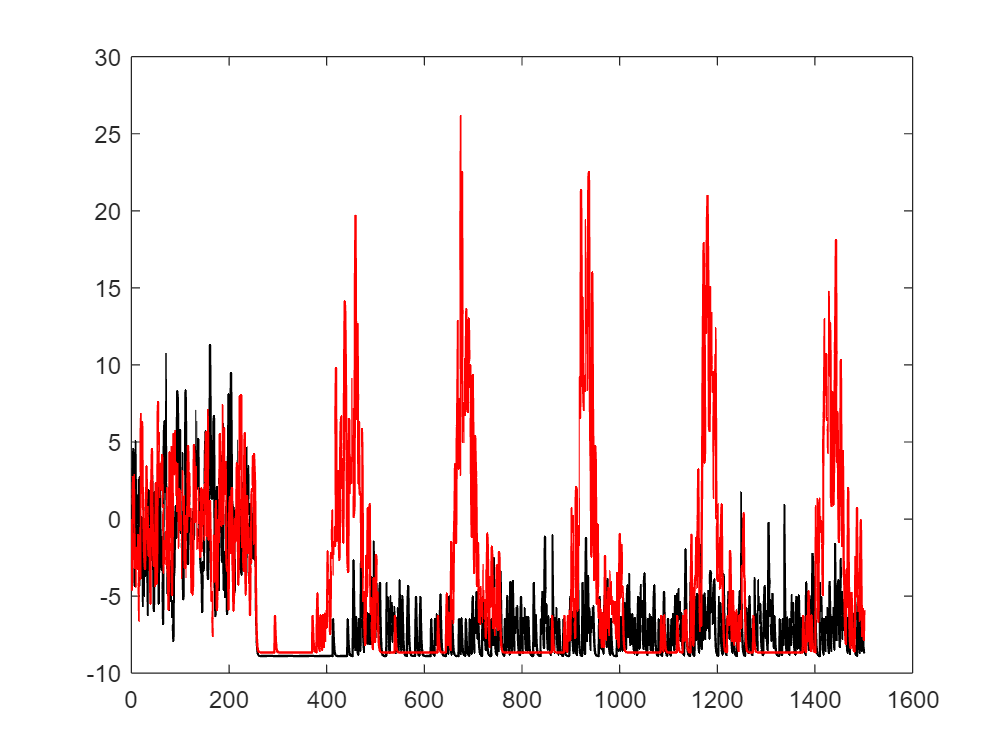

ind1 = 156;
plot(nanmean(bc_lfp2(t1(ind1),:,:),3), 'color', 'k', 'linewidth', 1)
hold on;
plot(nanmean(bc_lfp(t1(ind1),:,:),3), 'color', 'r', 'linewidth', 1)
hold off;